# System Integration and Test Simulation

Configure a simulation that uses the following:

- Truth Locations - Field-collected ADSB data recorded with an RTL-SDR

- Detections and Sensor-based Tracks:

- Active radar (fusionRadarSensor)

- ADSB data (gpsSensor and ADSBReceiver)

- TrackFuser for C2 level tracks

- OSPA Metric, trackAssignmentMetrics, and errorMetrics for track accuracy analysis

close all force; clear all; addpath('../HelperFunctions/')

Import truth location of aircraft and prerecorded sensor data

mapOrigin = [42.39423231362 -70.95934958874 0]; % Also defined in helperNed2ecefTrack, helperEcef2nedTrack, and fusionAlgorithm.m
load('TruthData.mat'); % Load Truth Trajectories
load('SensorData.mat'); % Load Pre-recorded Sensor Data

## Configure Simulation

### Setup Scenario

Scenario Creation includes configuring the Active Radar Sensor

truncatedStopTime = 60; % Limit Simulation time (s)
[scenario, mapViewer, activeRadarData] = helperCreateScenario(tuningData,mapOrigin,sensorData,truncatedStopTime);

%snapshot(mapViewer); % Only supported in MATLAB Desktop

### Configure Radar Tracker

[tracker,activeRadarSpec,targetSpec] = helperCreateTracker(scenario);

### Configure Secondary Sensor

Add ADSB for secondary target detection

Define Accuracy parameters for the gps sensor and assign ADSB transponder a

horAccuracy = 30;   % meters (NACp = 9)
vertAccuracy = 45;  % meters (NACp = 9)
velAccuracy = 0.6;  % m/s (NACv = 3)

## **Step 1 - Configure the gpsSensor to be used for ADSB**

**Directions:**

Assign an instance of 'gpsSensor' to the variable 'gps'

Use 'gpsSensor' function with the following name-value pairs to configure the gpsSensor to simulate ADSB accuracie:

- Set 'PositionInputFormat' to **'Geodetic'**

- Set 'HorizontalPositionAccuracy' to **horAccuracy**, the variable defined above

- Set 'VerticalPositionAccuracy' to **vertAccuracy**, the variable defined above

- Set 'VelocityAccuracy' to **velAccuracy**, the variable defined above

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% type "doc gpsSensor" in the Command Window to find the documentation page for this function
gps = gpsSensor('PositionInputFormat','Geodetic',...
    'HorizontalPositionAccuracy',horAccuracy,...
    'VerticalPositionAccuracy',vertAccuracy,'VelocityAccuracy',velAccuracy);

Leverage the provided helper function to store GPS transponder in a structure.

transponderStruct = helperCreateTX(scenario, gps);

### Configure ADSB Receiver for SSR

adsbRx = adsbReceiver('ReceiverIndex',2);
adsbRange = 2e5; % m

### Configure Track Fuser

You fuse radar tracks with ADS-B tracks obtained from the ADS-B receiver. To do this, you configure a central `trackFuser` object.

Define Process Noise for Fuser

procNoiseHorz = 3*targetSpec{1}.MaxHorizontalAcceleration^2/3;
procNoiseVert = 3*targetSpec{1}.MaxVerticalAcceleration^2/3;
fuseProcNoise = blkdiag(procNoiseHorz,procNoiseHorz,procNoiseVert);

Instantiate Fuser

fuser = trackFuser('FuserIndex',3,'MaxNumSources',2,...
    "AssignmentThreshold",[150 200],...
    "StateFusion",'Intersection',... % 'Cross'
    'StateFusionParameters','trace',... % '0.5'
    'ProcessNoise',fuseProcNoise, ...
    'ConfirmationThreshold',[5 7],...
    'DeletionThreshold', [5 8],...
    'FuseCoasted',true);
%fuser2 = clone(fuser);

### Configure Metrics

ospa = trackOSPAMetric('CutoffDistance',500,'Distance','posabserr'); %,'LabelingError',500
errorMetrics = trackErrorMetrics;
assignmentMetrics = trackAssignmentMetrics(...
    'AssignmentDistance','posabserr',...
    'DivergenceDistance','posabserr',...
    'DivergenceThreshold',50,...
    'AssignmentThreshold',50);

## Run Simulation

Run a small number of steps with the User-defined fuser so you can see whether ADS-B tracks are landing on or far from the truth positions. If the adsbConfig is wrong, tracks will appear displaced on the globe.

**Check the figure and consider:**

- If ADS-B/fused tracks are displaced from truth, fix adsbConfig above and re-run

- If tracks overlay the truth, your config is correct — proceed to Phase 2

numStepsToRun = numel(activeRadarData);
a1 = tic;
towerPos = scenario.Platforms{1};
stationaryIDs = [1, 2];  % Omit stationary platforms

%[mapViewer,scenario,tracker,adsbRx,fuser,transponderStruct] = helperResetAll(mapViewer,scenario,tracker,adsbRx,fuser,transponderStruct);

for ind = 1:numStepsToRun
    advance(scenario);

    % Define Current Simulation Time
    time = scenario.SimulationTime;

    % Preallocate
    adsbTracks     = objectTrack.empty;
    adsbTracksNED = objectTrack.empty;
    radarTracks    = objectTrack.empty;
    fusedTracks    = objectTrack.empty;

    % Plot Radar Coverage
    covcon = coverageConfig(scenario);
    plotCoverage(mapViewer,covcon,"ECEF")

    % Plot Truth positions
    truePosePlot = platformPoses(scenario);
    plotPlatform(mapViewer, truePosePlot, 'ECEF');

    % Plot Radar Detections
    helperPlotActiveRadarData(mapViewer, activeRadarSpec, activeRadarData(ind));
    
    % Generate ADSB Messages with Range-Based ADSB Dropout
    clear adsbMessages
    adsbMessages = generateADSBMessages(scenario,transponderStruct,time,mapOrigin,adsbRange);

    % Only call ADSB Receive if messages exist at this Timestep
    if ~isempty(adsbMessages)
        adsbTracks = adsbRx(adsbMessages, time);
        adsbTracks = helperEnsureTimeAndParams(adsbTracks, time, helperEcefParams());
        % Convert ADSB Tracks to NED
        for i = 1:length(adsbTracks)
            adsbTracksNED(i) = helperEcef2nedTrack(adsbTracks(i),mapOrigin);
        end
    else
        adsbTracks = objectTrack.empty;
    end
    
    % Generate Radar Tracks
    radarTracksStruct = trackingAlgorithm_mex({activeRadarData(ind)},targetSpec,activeRadarSpec);
    %radarTracksStruct = trackingAlgorithm({activeRadarData(ind)},targetSpec,activeRadarSpec);
    radarTracks = helperConvertToObjectTrack(radarTracksStruct);
    radarTracks = helperEnsureTimeAndParams(radarTracks, time, helperNedParams(mapOrigin));

    % Fusion
    if isLocked(fuser) || ~isempty([adsbTracksNED';radarTracks])
        %fusedTracks = fuser([adsbTracks;radarTracks], time); % Fuser configuration required
        fusedTracks = fuser([adsbTracksNED';radarTracks], time); % If preprocess adsbTracks to NED
    end

    % Plot all tracks
    mapViewer = helperPlotTracks(3,ind,mapViewer,scenario, adsbTracksNED,radarTracks,fusedTracks);

    drawnow;

    % Collect Metrics
    truePoseNED = targetPoses(towerPos); % Note Indexing is shifted by one, omits the reference platform
    truthsForMetrics{ind} = truePoseNED(~ismember([truePoseNED.PlatformID], stationaryIDs));
    adsbTrackLog{ind} = adsbTracksNED;
    radarTrackLog{ind} = radarTracks;
    fusedTrackLog{ind} = fusedTracks;

    % Fused Track Metrics
    [trackAssignmentSummary(ind), truthAssignmentSummary(ind)] = assignmentMetrics(fusedTracks, truthsForMetrics{ind});
    [assignedTrackIDs, assignedTruthIDs] = currentAssignment(assignmentMetrics);
    [posRMSE(ind), velRMSE(ind), posANEES(ind), velANEES(ind)] = errorMetrics(fusedTracks, assignedTrackIDs, truthsForMetrics{ind}, assignedTruthIDs);
    trackError{ind} = cumulativeTrackMetrics(errorMetrics);
    truthError{ind} = cumulativeTruthMetrics(errorMetrics);
    assignedTruthIDsPerTime{ind} = assignedTruthIDs;
end
fprintf('Phase 1 complete (%.1f s).  Check the globe viewer.\n', toc(a1));

Phase 1 complete (65.1 s).  Check the globe viewer.


% snapshot(mapViewer); % Only supported in MATLAB Desktop

Change camera point of view to zoom in on radar FOV

cameraPos = 1.0e+03 *[0.0420   -0.0717    5.1059];
campos(mapViewer,cameraPos(1),cameraPos(2),cameraPos(3));
cameraOri = [79.3398   -8.6789    0.0141];
camorient(mapViewer,cameraOri);

### Visualize Metrics

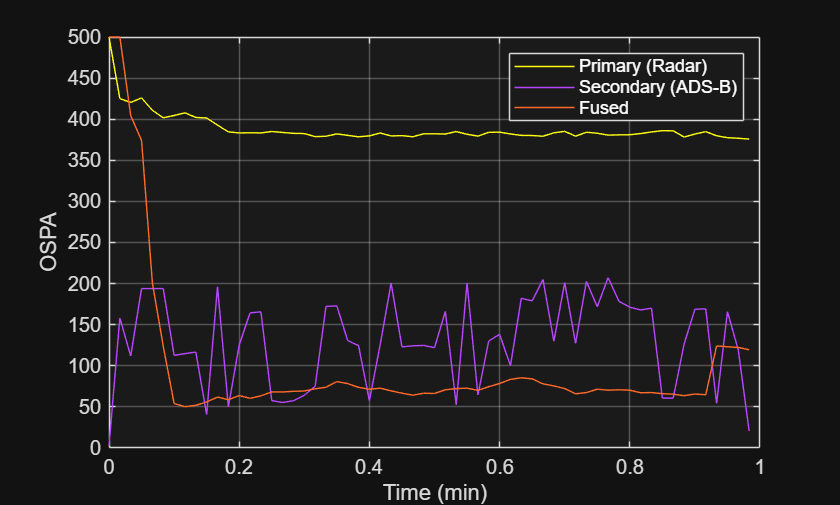

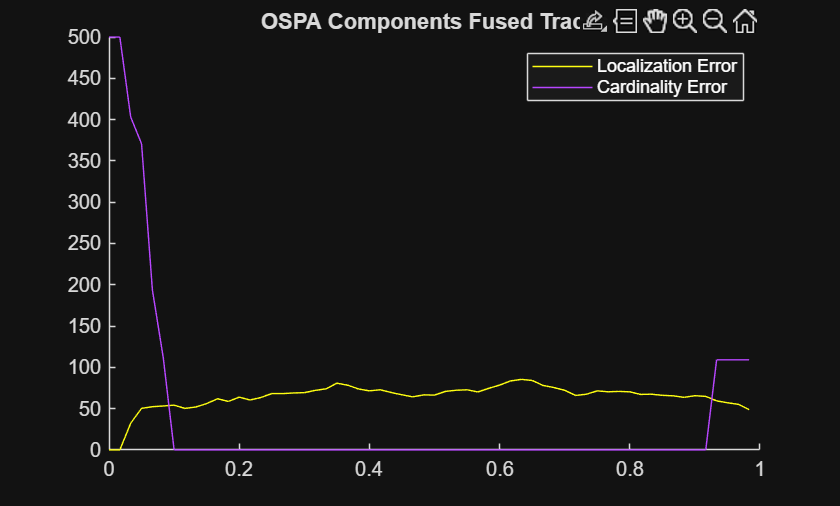

[radarospa,adsbospa,fusedospa] = helperCollectOSPAMetricsAndPlot(ospa,truthsForMetrics,radarTrackLog,adsbTrackLog,fusedTrackLog);

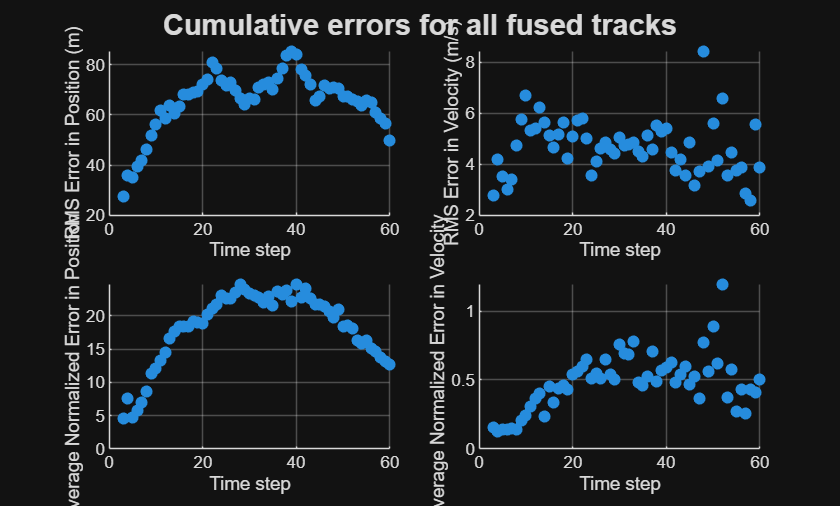

helperPlotRMS(posRMSE,velRMSE,posANEES,velANEES)

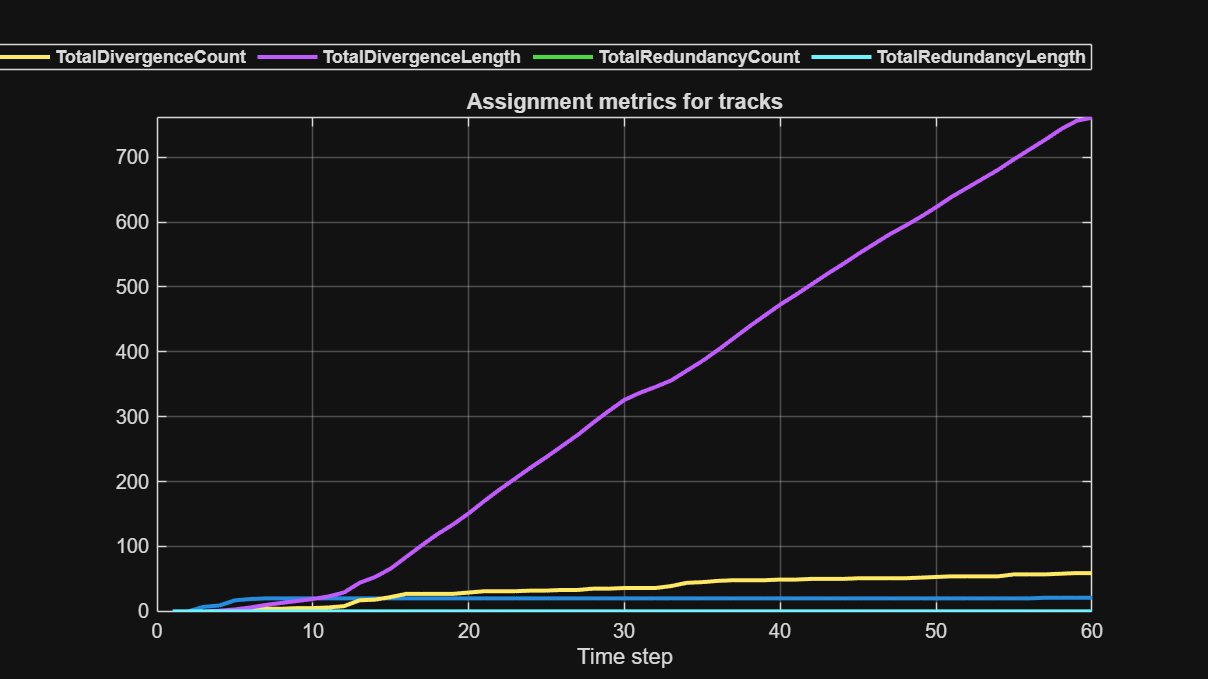

%  Troubleshooting
% viewer = trackingGlobeViewer;
% %plotDetection(viewer,activeRadarData)
% for i = 1:size(activeRadarData,1)
%     helperPlotActiveRadarData(viewer, activeRadarSpec, activeRadarData(i));
% end

function helperPlotStructArray(~, st)

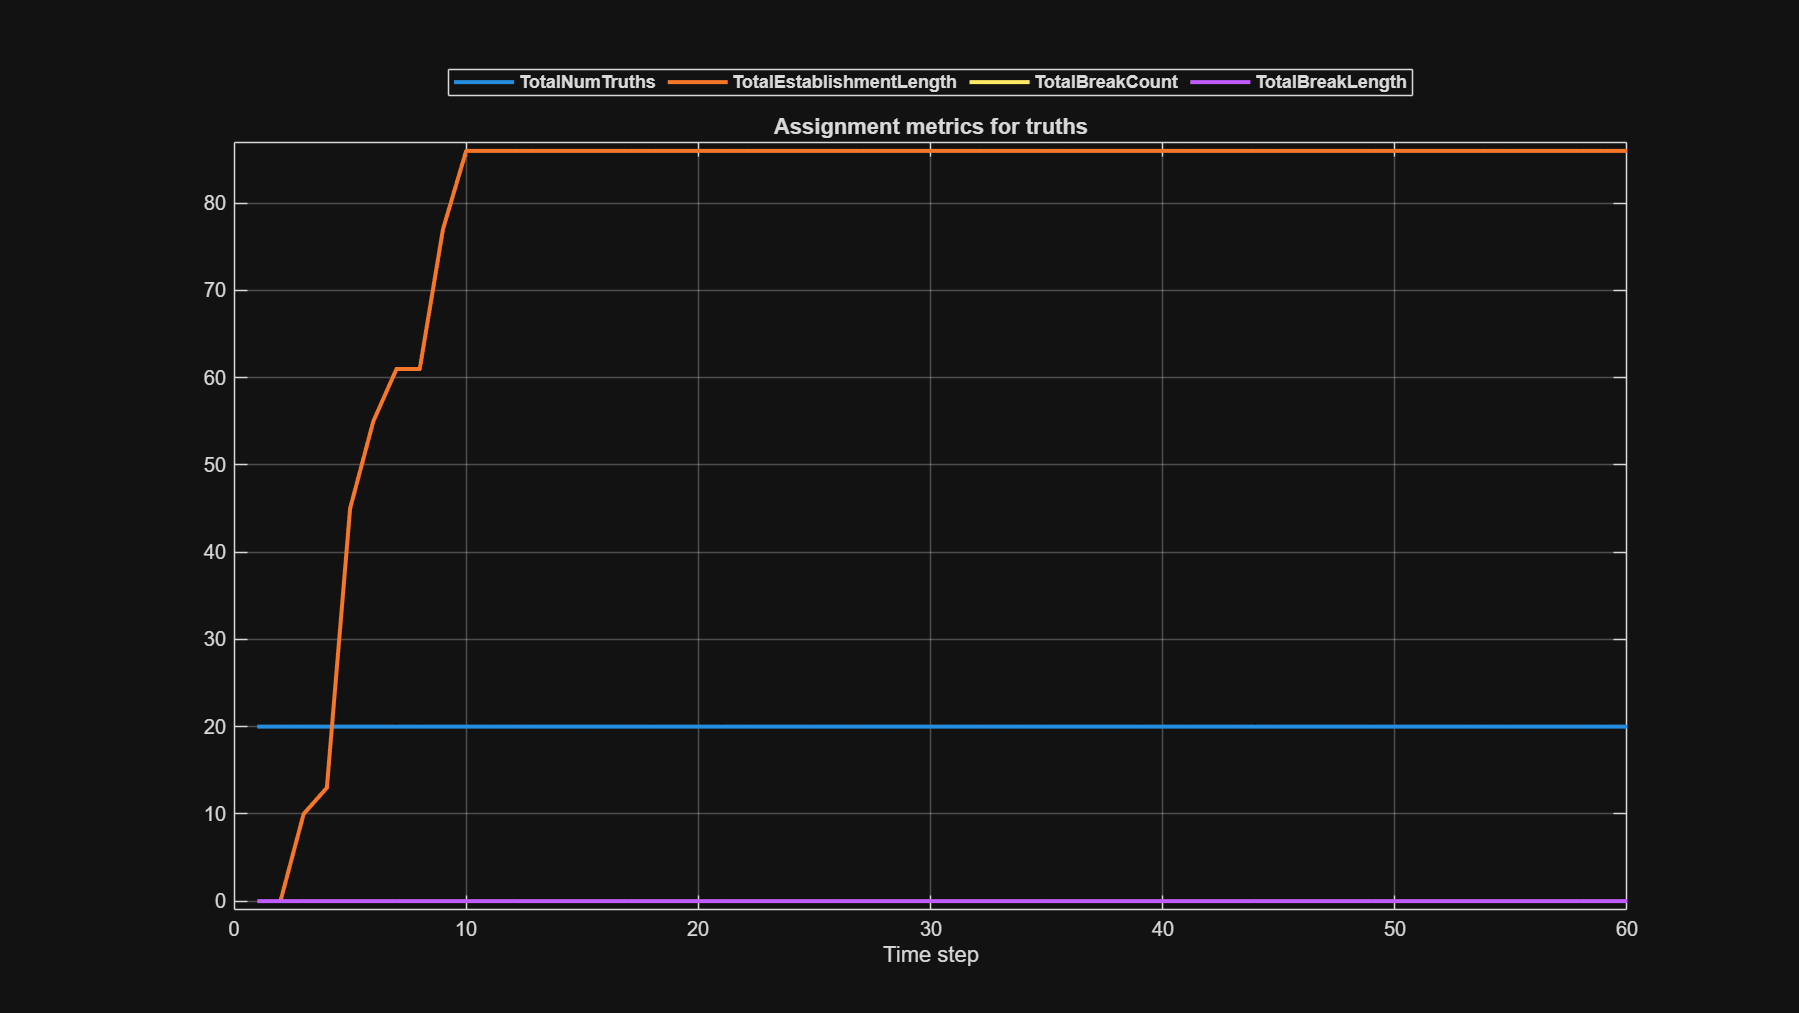

fig = figure('Units','normalized','Position',[0.1 0.1 0.6 0.6]);

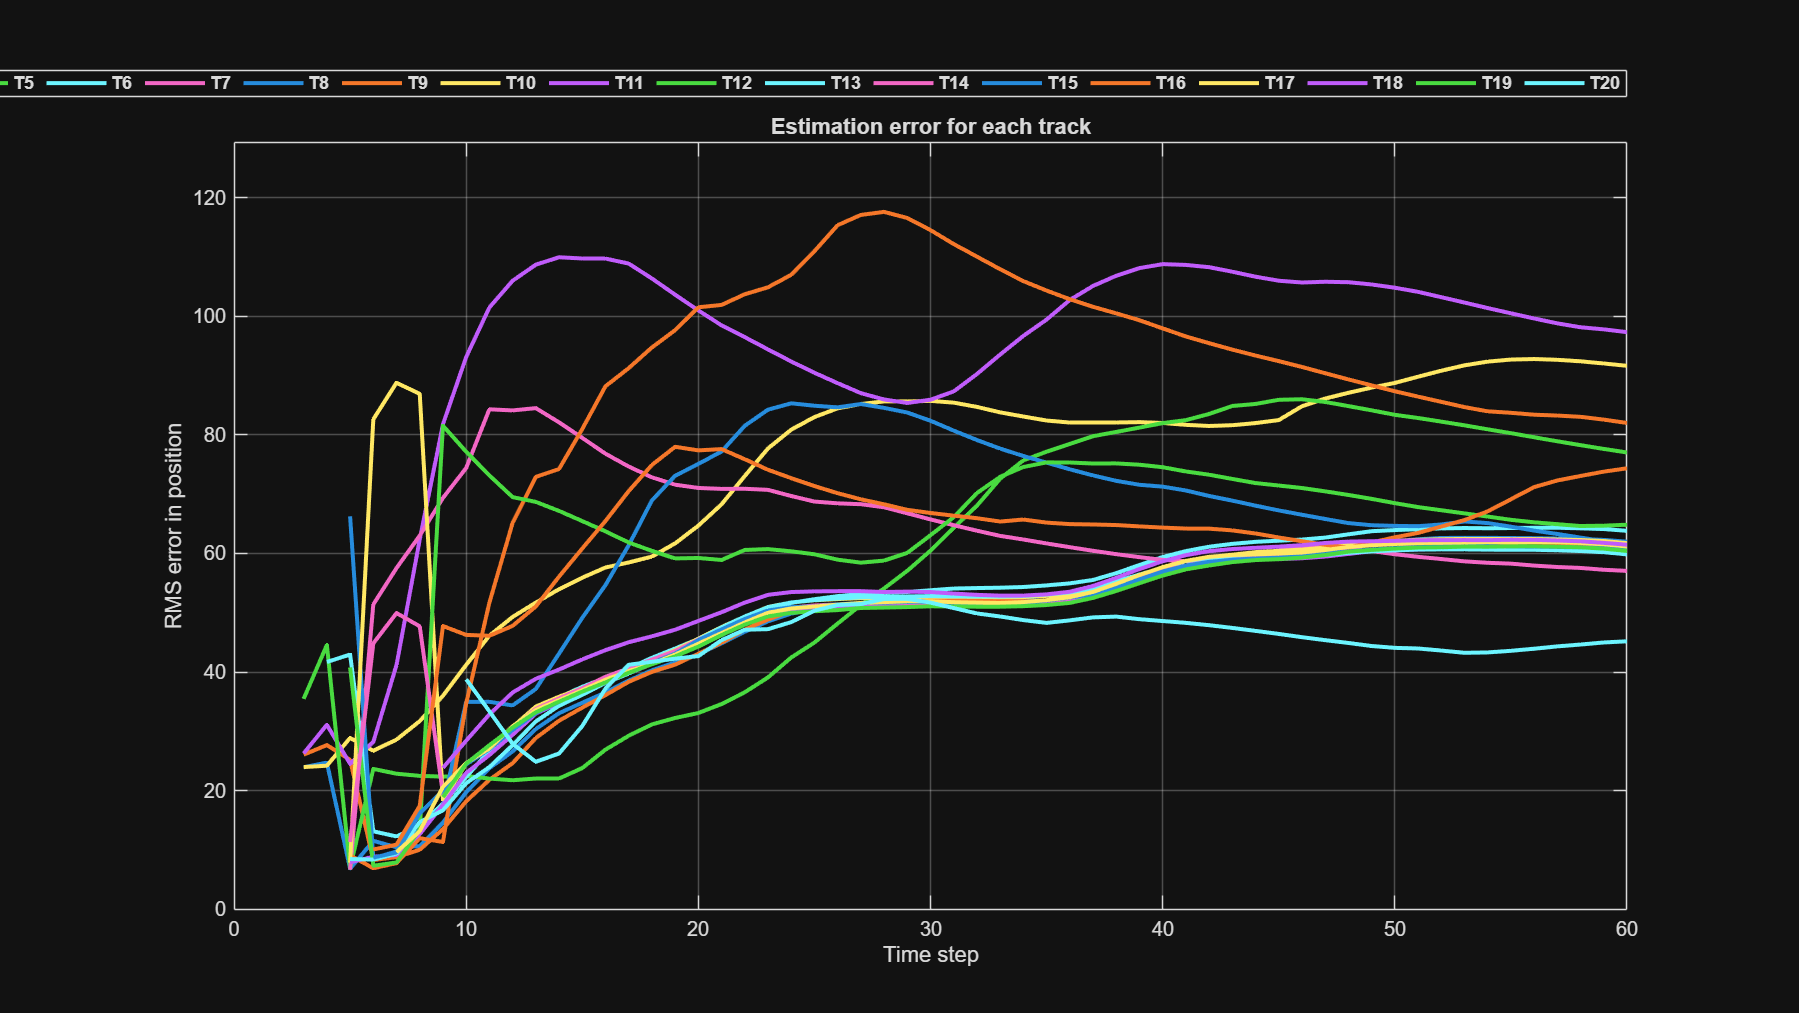

ax = axes(fig);

fNames = fieldnames(st);

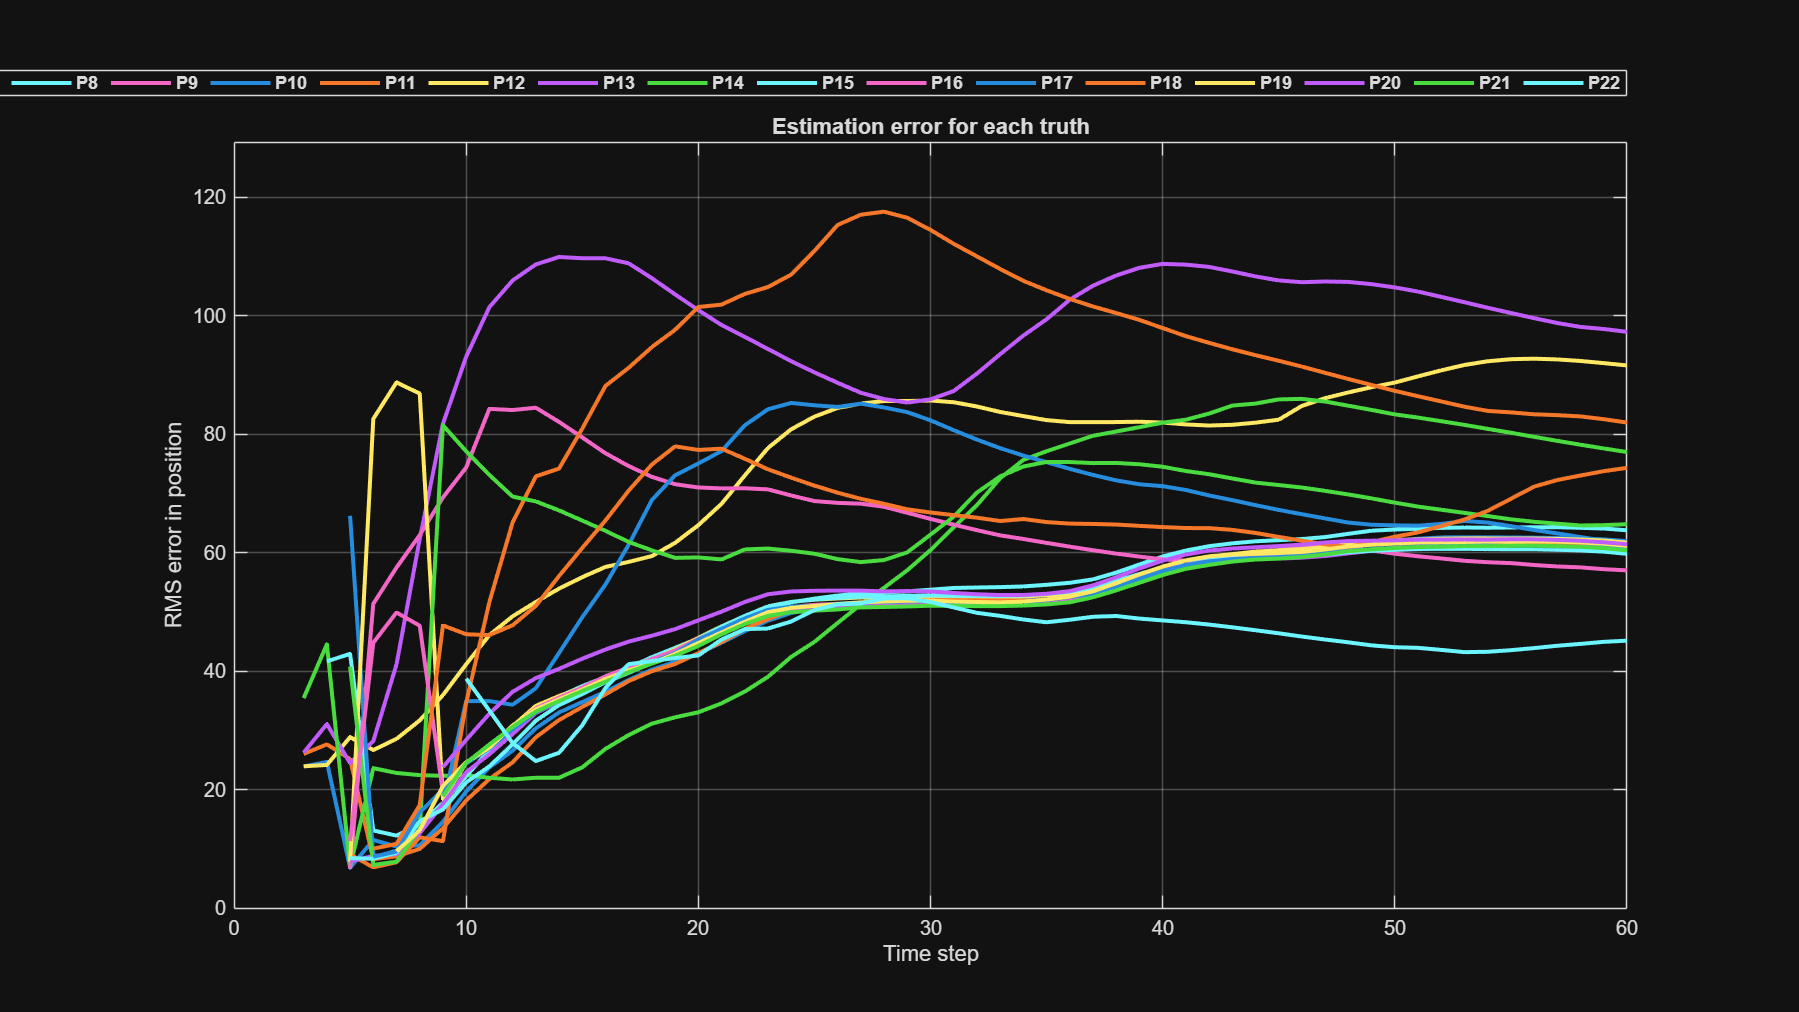

if isfield(st,'TotalNumTracks')

    titleStr = 'Assignment metrics for tracks';
else
    titleStr = 'Assignment metrics for truths';
end

fNames = fNames(contains(fNames,{'Total'}));
thisF = zeros(numel(st),numel(fNames));
for i = 1:numel(fNames)
    thisF(:,i) = [st.(fNames{i})];
end
plot(ax, thisF,'LineWidth',2);
maxY = max(thisF(:));
minY = min(thisF(:));
ylim(ax,[minY-1,maxY+1]);

l = legend(fNames{:});
l.Location = 'North outside';
l.Orientation = 'horizontal';
l.FontWeight = 'bold';
xlabel(ax,'Time step');
grid(ax,'on');
title(ax,titleStr);
end

function helperPlotTableArray(~,tArray,errorToPlot)
[maxIds,idx] = max(cellfun(@(x)size(x,1),tArray));
data = nan(numel(tArray),maxIds);
for i = 1:numel(tArray)
    thisData = tArray{i}.(errorToPlot);
    data(i,1:numel(thisData)) = thisData;
end
fig = figure('Units','normalized','Position',[0.1 0.1 0.6 0.6]);
ax = axes(fig);
grid(ax,'on');
plot(ax,data,'LineWidth',2);
maxY = max(data(:));
minY = min(data(:));
ylim(ax,[min(0.9*minY,-0.1),1.1*maxY]);

varName = tArray{idx}.Properties.VariableNames{1};
names = string([tArray{idx}.(varName)]);
if strcmpi(varName,'TrackID')
    names = strcat("T",names);
    titleStr = 'Estimation error for each track';
else
    names = strcat("P",names);
    titleStr = 'Estimation error for each truth';
end
title(ax,titleStr);
l = legend(names);
l.Location = 'North outside';
l.Orientation = 'horizontal';
l.FontWeight = 'bold';
xlabel(ax,'Time step');
switch errorToPlot
    case 'posRMS'
        str = "RMS error in position";
    case 'velRMS'
        str = "RMS error in velocity";
    case 'posNEES'
        str = "Normalized error in position";
    case 'velNEES'
        str = "Normalized error in velocity";
    otherwise
        str = errorToPlot;
end

ylabel(ax,str);
grid(ax,'on');
end


helperPlotStructArray(1,trackAssignmentSummary)
helperPlotStructArray(1,truthAssignmentSummary);


helperPlotTableArray(1,trackError,'posRMS');
helperPlotTableArray(1,truthError,'posRMS');

## Phase 2 — Full Simulation with MEX Fuser - Show in Full Simulation

Phase 2 uses the MEX-compiled fusionAlgorithm (which has its own correct hardcoded config) for the full-duration simulation with metrics.

This is wrapped in helperRunFullSimulation() for a clean, single function call:

### Run Full Simulation

helperRunFullSimulation re-creates the scenario, tracker, and fuser from scratch using the MEX-compiled fusionAlgorithm_mex, runs the full simulation, and returns all logged data and metrics.

% % Clean up the interpreted fuser from Phase 1
% clear trackingAlgorithm_mex
% results = helperRunFullSimulation(tuningData, mapOrigin,fuser2);

### Take Snapshot of Viewer (from Phase 2 - Full Simulation)

%snapshot(results.mapViewer); % Only works on MATLAB Desktop

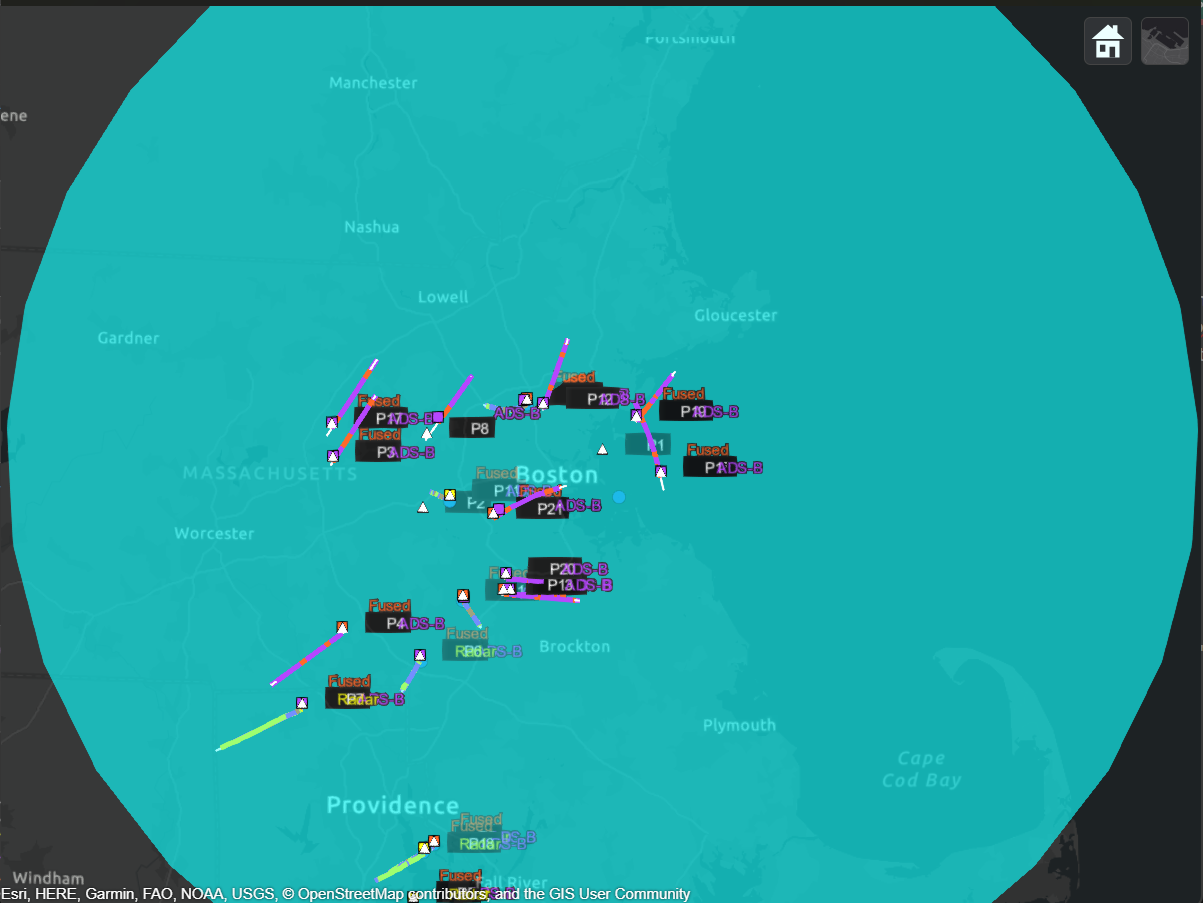

Change camera point of view to zoom in on radar FOV

% cameraPos = 1.0e+03 *[0.0420   -0.0717    5.1059];
% campos(results.mapViewer,cameraPos(1),cameraPos(2),cameraPos(3));
% cameraOri = [79.3398   -8.6789    0.0141];
% camorient(results.mapViewer,cameraOri);
% %snapshot(results.mapViewer); % Only works on MATLAB Desktop

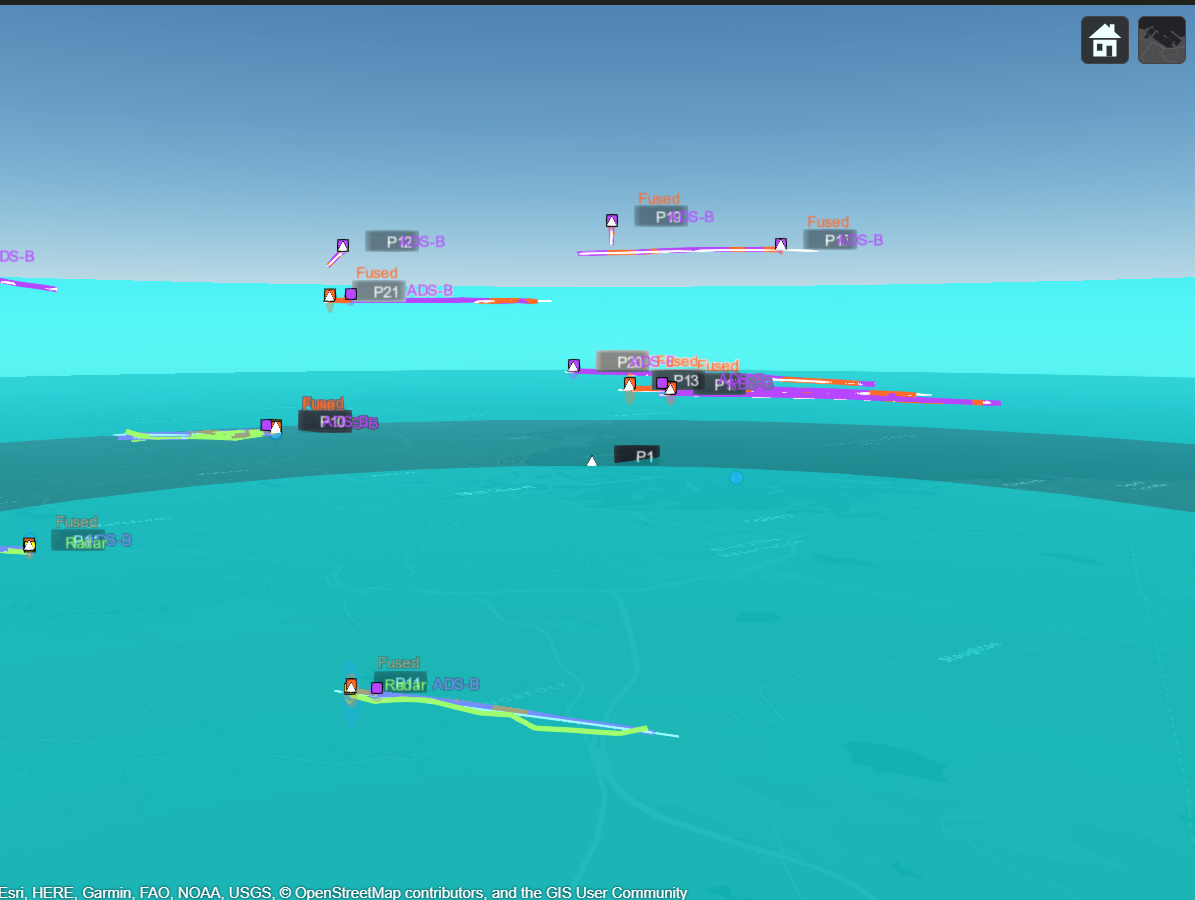

## Collect and Visualize Metrics

### Plot OSPA Metrics

helperCollectOSPAMetricsAndPlot(ospa,results);

### Plot RMS Values

helperPlotRMS(results)

numSteps = numel(results.trackAssignmentSummary);
divergenceCount = zeros(numSteps, 1);
divergenceLength = zeros(numSteps, 1);
swapCount = zeros(numSteps, 1);
falseTracks = zeros(numSteps, 1);

for i = 1:numSteps
    divergenceCount(i) = results.trackAssignmentSummary(i).TotalDivergenceCount;
    divergenceLength(i) = results.trackAssignmentSummary(i).TotalDivergenceLength;
    swapCount(i) = results.trackAssignmentSummary(i).TotalSwapCount;
    falseTracks(i) = results.trackAssignmentSummary(i).NumFalseTracks;
end

% Plot track continuity metrics
timeVector = 1:numSteps;  % Or use actual time if available

figure;
subplot(2,2,1);
plot(timeVector, divergenceCount);
title('Track Breaks (Cumulative)');
xlabel('Simulation Timestep'); ylabel('Total Count');

subplot(2,2,2);
plot(timeVector, divergenceLength);
title('Lost Track Duration (Cumulative)');
xlabel('Simulation Timestep'); ylabel('Total Timesteps Lost');

subplot(2,2,3);
plot(timeVector, swapCount);
title('Track ID Switches (Cumulative)');
xlabel('Simulation Timestep'); ylabel('Total Swaps');

subplot(2,2,4);
plot(timeVector, falseTracks);
title('False Tracks');
xlabel('Simulation Timestep'); ylabel('Count');

% Diagnostics
%% === TARGET COVERAGE ANALYSIS (Using Truth Assignments) ===
fprintf('\n=== ANALYZING FUSED TRACK COVERAGE BY TRUTH ID ===\n');
assignedTruthIDsPerTime = results.assignedTruthIDs;
numSteps = length(assignedTruthIDsPerTime);
numTargets = 20;

% Track which truths were assigned at each step
fusedCoverage = false(numTargets, numSteps);

for stepIdx = 1:numSteps
    assignedTruths = assignedTruthIDsPerTime{stepIdx};

    if ~isempty(assignedTruths)
        % Mark these truths as having a fused track
        fusedCoverage(assignedTruths, stepIdx) = true;
    end
end

%% Per-target analysis
fprintf('\nPer-Target Fusion Success:\n');
fprintf('Truth  Fused    Percent    Status\n');
fprintf('  ID   Steps              \n');
fprintf('-----  -----    -------    ----------\n');

problemTargets = [];

for i = 1:numTargets
    fusedSteps = sum(fusedCoverage(i, :));
    pct = 100 * fusedSteps / numSteps;

    if pct < 60
        status = '⚠️ PROBLEM (likely ADS-B-only)';
        problemTargets = [problemTargets, i];
    elseif pct < 85
        status = '⚠ Marginal';
    else
        status = '✓ Good';
    end

    fprintf('%3d    %2d/%2d    %5.1f%%    %s\n', ...
        i, fusedSteps, numSteps, pct, status);
end

fprintf('\n=== SUMMARY ===\n');
fprintf('Problem targets (<60%% coverage): %s\n', mat2str(problemTargets));
fprintf('Total problematic targets: %d\n', length(problemTargets));

if ~isempty(problemTargets)
    fprintf('\nThese targets are likely:\n');
    fprintf('  - Outside radar FOV (ADS-B-only)\n');
    fprintf('  - Experiencing excessive ADS-B dropout\n');
    fprintf('  - Failing ConfirmationThreshold requirements\n');
end

%% Coverage timeline visualization
figure('Name', 'Fused Track Coverage by Truth ID');
imagesc(fusedCoverage);
colormap([0.8 0.2 0.2; 0.2 0.8 0.2]); % Red = not tracked, Green = tracked
xlabel('Time Step');
ylabel('Truth Target ID');
title('Fused Track Coverage (Green = Tracked, Red = Missing)');
cb = colorbar('Ticks', [0.25, 0.75], 'TickLabels', {'Missing', 'Tracked'});
cb.Label.String = 'Coverage Status';
set(gca, 'YDir', 'normal');
grid on;

% Highlight problem targets
if ~isempty(problemTargets)
    hold on;
    for i = 1:length(problemTargets)
        % Draw red boxes around problem targets
        rectangle('Position', [0.5, problemTargets(i)-0.5, numSteps, 1], ...
            'EdgeColor', 'r', 'LineWidth', 2, 'LineStyle', '--');
    end
end

%% Track loss event timeline
fprintf('\n=== TRACK LOSS/GAIN EVENTS ===\n');

lossEvents = [];
gainEvents = [];

for stepIdx = 2:numSteps
    % Compare current step to previous
    prevAssigned = fusedCoverage(:, stepIdx-1);
    currAssigned = fusedCoverage(:, stepIdx);

    % Find tracks that were lost
    lostTracks = find(prevAssigned & ~currAssigned);

    % Find tracks that were gained
    gainedTracks = find(~prevAssigned & currAssigned);

    if ~isempty(lostTracks)
        lossEvents = [lossEvents; [stepIdx * ones(length(lostTracks), 1), lostTracks]];
        fprintf('Step %2d: LOST truth IDs: %s\n', stepIdx, mat2str(lostTracks'));
    end

    if ~isempty(gainedTracks)
        gainEvents = [gainEvents; [stepIdx * ones(length(gainedTracks), 1), gainedTracks]];
        % Only print if these are problem targets (to reduce noise)
        problemGains = intersect(gainedTracks, problemTargets);
        if ~isempty(problemGains)
            fprintf('Step %2d: GAINED truth IDs: %s ⚠️\n', stepIdx, mat2str(problemGains'));
        end
    end
end

%% Count track breaks for problem targets
if ~isempty(problemTargets)
    fprintf('\n=== TRACK CONTINUITY FOR PROBLEM TARGETS ===\n');
    fprintf('Truth  Total    Track    Avg Gap    Longest\n');
    fprintf('  ID   Breaks   Uptime   (steps)    Gap\n');
    fprintf('-----  ------   ------   -------    -------\n');

    for i = 1:length(problemTargets)
        truthID = problemTargets(i);
        coverage = fusedCoverage(truthID, :);

        % Count transitions from tracked to not-tracked
        breaks = sum(diff([0, coverage, 0]) == -1);

        % Calculate gap lengths
        gaps = [];
        inGap = false;
        gapLength = 0;

        for step = 1:numSteps
            if ~coverage(step)
                if ~inGap
                    inGap = true;
                    gapLength = 1;
                else
                    gapLength = gapLength + 1;
                end
            else
                if inGap
                    gaps = [gaps, gapLength];
                    inGap = false;
                    gapLength = 0;
                end
            end
        end

        if inGap
            gaps = [gaps, gapLength];
        end

        if isempty(gaps)
            avgGap = 0;
            maxGap = 0;
        else
            avgGap = mean(gaps);
            maxGap = max(gaps);
        end

        uptime = sum(coverage);

        fprintf('%3d    %4d     %2d/%2d    %5.1f      %4d\n', ...
            truthID, breaks, uptime, numSteps, avgGap, maxGap);
    end
end

%% Overall unassigned truth timeline
figure('Name', 'Tracking Performance Over Time');
subplot(2,1,1);
unassignedPerStep = numTargets - sum(fusedCoverage, 1);
plot(1:numSteps, unassignedPerStep, 'r-', 'LineWidth', 2);
hold on;
yline(0, 'g--', 'Perfect Tracking', 'LineWidth', 1.5);
xlabel('Time Step');
ylabel('Unassigned Truths');
title('Number of Targets Without Fused Tracks');
grid on;
ylim([-1, max(unassignedPerStep) + 2]);

subplot(2,1,2);
assignedPerStep = sum(fusedCoverage, 1);
plot(1:numSteps, assignedPerStep, 'g-', 'LineWidth', 2);
hold on;
yline(numTargets, 'k--', sprintf('Goal (%d targets)', numTargets), 'LineWidth', 1.5);
xlabel('Time Step');
ylabel('Assigned Truths');
title('Number of Targets With Fused Tracks');
grid on;
ylim([0, numTargets + 2]);

## BONUS:

Consider running "Exercise3_BONUS" for further breakdown of metrics

function templateADSBMessage = generateTemplateADSBMessage
templateADSBMessage = struct('ICAO', 'MW2020',...
    'Time', '',...
    'Category','',...
    'Callsign','',...
    'Latitude',NaN,...
    'Longitude',NaN,...
    'Altitude',NaN,...
    'Veast',NaN,...
    'Vnorth',NaN,...
    'ClimbRate',NaN,...
    'Heading',NaN,...
    'NACPosition', NaN,...
    'GeometricVerticalAccuracy',NaN,...
    'NACVelocity',NaN);
end

function cartDistance = ADSBTargetRange(stationsLLA, pos) %cartDistance
cartDistance = fusion.internal.frames.lla2ecef(stationsLLA) - fusion.internal.frames.lla2ecef(pos);
%flag = any(vecnorm(cartDistance,2,2) < range);
end

function adsbMessages = generateADSBMessages(scenario,transponderStruct,time,mapOrigin,adsbRange)
adsbMessages = generateTemplateADSBMessage;
adsbMessages(1)=[]; % Clear Values from structure

for i = 3:numel(scenario.Platforms) % omit Stationary Towers
    poseStruct = pose(scenario.Platforms{i},'CoordinateSystem','Geodetic');
    poseStruct.PlatformID = scenario.Platforms{i}.PlatformID;
    truePoseGPS(i) = poseStruct;

    position = truePoseGPS(i).Position;
    velocity = truePoseGPS(i).Velocity;

    % Confirm Position Values exist
    isValid = all(~isnan(position));

    % Augment PDrop according to range
    PDropClose = 0.02;   % 5% dropout at close range
    PDropFar = 0.3;      % 30% dropout at max range
    cartDistance = ADSBTargetRange(mapOrigin, position);
    range_m = norm(cartDistance);
    rangeFactor = range_m / adsbRange;
    actualPDrop  = PDropClose + (PDropFar - PDropClose) * rangeFactor;
    keepMsg = rand >= actualPDrop;

    if isValid && keepMsg
        msg = transponderStruct(i-2).adsbTx(position,velocity);
        msg.Time = time;
        adsbMessages = [adsbMessages; msg];
    end
end

end

function [mapViewer,scenario,tracker,adsbRx,fuser,transponderStruct] = helperResetAll(mapViewer,scenario,tracker,adsbRx,fuser,transponderStruct)
% Reset for Phase 1
if exist("mapViewer")
    clear(mapViewer);
end
restart(scenario);
release(tracker);
reset(adsbRx);
reset(fuser)

for i = 1:length(scenario.Platforms)-2
    reset(transponderStruct(i).adsbTx);
end
end

% function [results] = helperCollectMetrics(ind,scenario,assignmentMetrics,errorMetrics,fusedTracks)
% NEDPlat = scenario.Platforms{1};
% truePoseNED = targetPoses(NEDPlat); % Note Indexing is shifted by one, omits the reference platform
% stationaryIDs = [1, 2];  % Adjust based on your scenario - omit stationary platforms
% truthsForMetrics = truePoseNED(~ismember([truePoseNED.PlatformID], stationaryIDs));
% 
% % Fused
% [trackAssignmentSummary(ind), truthAssignmentSummary(ind)] = assignmentMetrics(fusedTracks, truthsForMetrics);
% [assignedTrackIDs, assignedTruthIDs] = currentAssignment(assignmentMetrics);
% [posRMSE(ind), velRMSE(ind), posANEES(ind), velANEES(ind)] = errorMetrics(fusedTracks, assignedTrackIDs, truthsForMetrics, assignedTruthIDs);
% trackError{ind} = cumulativeTrackMetrics(errorMetrics);
% truthError{ind} = cumulativeTruthMetrics(errorMetrics);
% assignedTruthIDsPerTime{ind} = assignedTruthIDs;
% 
% %% ---- Package results ----
% results.posRMSE  = posRMSE;
% results.velRMSE  = velRMSE;
% results.posANEES = posANEES;
% results.velANEES = velANEES;
% 
% results.trackError = trackError;
% results.truthError = truthError;
% results.trackAssignmentSummary = trackAssignmentSummary;
% results.truthAssignmentSummary = truthAssignmentSummary;
% 
% results.assignedTruthIDs = assignedTruthIDsPerTime;
% end